# Energy Prices - Importing

Open and inspect the file `EnergyPrices.xls` in Excel.  This file contains time and price information for two sources of energy on two different sheets. 

## 1.

Import the data from the first sheet into a table named `electricity`. Create a datetime vector `Date` by converting the times from the imported table.

electricity = readtable('EnergyPrices.xls','Sheet','Electricity')

electricity = 52608×2 table
       Time       Price
    __________    _____
    7.3195e+05    40.87
    7.3195e+05    38.97
    7.3195e+05    35.93
    7.3195e+05    34.79
    7.3195e+05    34.79
    7.3195e+05    35.39
    7.3195e+05    38.97
    7.3195e+05    40.76
    7.3195e+05    42.11
    7.3195e+05    44.26
    7.3195e+05    46.38
    7.3195e+05    46.17
    7.3195e+05    45.23
    7.3195e+05     43.9
    7.3195e+05    41.58
    7.3195e+05    44.62

Dates = datetime(electricity.Time,'ConvertFrom','datenum')

Dates = 52608×1 datetime array
   01-Jan-2004 00:00:00
   01-Jan-2004 01:00:00
   01-Jan-2004 02:00:00
   01-Jan-2004 03:00:00
   01-Jan-2004 04:00:00
   01-Jan-2004 05:00:00
   01-Jan-2004 06:00:00
   01-Jan-2004 07:00:00
   01-Jan-2004 08:00:00
   01-Jan-2004 09:00:00
   01-Jan-2004 10:00:00
   01-Jan-2004 11:00:00
   01-Jan-2004 12:00:00
   01-Jan-2004 13:00:00
   01-Jan-2004 14:00:00
   01-Jan-2004 15:00:00
   01-Jan-2004 16:00:00
   01-Jan-2004 17:00:00
   01-Jan-2004 18:00:00
   01-Jan-2004 19:00:00
   01-Jan-2004 20:00:00
   01-Jan-2004 21:00:00
   01-Jan-2004 22:00:00
   01-Jan-2004 23:00:00
   02-Jan-2004 00:00:00
   02-Jan-2004 01:00:00
   02-Jan-2004 02:00:00
   02-Jan-2004 03:00:00
   02-Jan-2004 04:00:00
   02-Jan-2004 05:00:00
   02-Jan-2004 06:00:00
   02-Jan-2004 07:00:00
   02-Jan-2004 08:00:00
   02-Jan-2004 09:00:00
   02-Jan-2004 10:00:00
   02-Jan-2004 11:00:00
   02-Jan-2004 12:00:00
   02-Jan-2004 13:00:00
   02-Jan-2004 14:00:00
   02-Jan-2004 15:00:00
   02-Jan

## 2. 

Create a logical variable called `isZeroPrice` that is true if the electricity price is exactly 0. Use this logical variable to perform a linear interpolation on electricity price. Plot Price vs. Date.

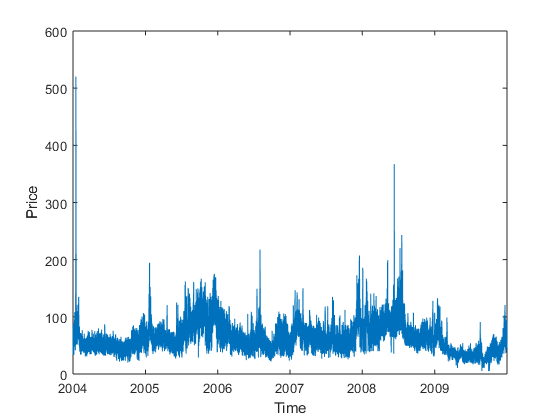

isZeroPrice = (electricity.Price == 0);
electricity.Price(isZeroPrice) = nan;
electricity.Price = fillmissing(electricity.Price,'linear',...
    'SamplePoints',electricity.Time);
plot(Dates, electricity.Price)
xlabel('Time')
ylabel('Price')

## 3.

Import the data from the second sheet into a table named `naturalGas`.

naturalGas = readtable('EnergyPrices.xls','Sheet', 'Natural Gas')

naturalGas = 52608×2 table
       Time       Price
    __________    _____
    7.3195e+05    5.825
    7.3195e+05    5.825
    7.3195e+05    5.825
    7.3195e+05    5.825
    7.3195e+05    5.825
    7.3195e+05    5.825
    7.3195e+05    5.825
    7.3195e+05    5.825
    7.3195e+05    5.825
    7.3195e+05    5.825
    7.3195e+05    5.825
    7.3195e+05    5.825
    7.3195e+05    5.825
    7.3195e+05    5.825
    7.3195e+05    5.825
    7.3195e+05    5.825

## 4.

Join the two tables into a new table called `energy`. Use the `Time` variable as the key. Change the names of variables 2 and 3 of `energy` to be `Electricity` and `NaturalGas`, respectively.

energy = join(electricity,naturalGas,'Keys','Time');
energy.Properties.VariableNames(2:3) = {'Electricity','NaturalGas'}

energy = 52608×3 table
       Time       Electricity    NaturalGas
    __________    ___________    __________
    7.3195e+05       40.87         5.825   
    7.3195e+05       38.97         5.825   
    7.3195e+05       35.93         5.825   
    7.3195e+05       34.79         5.825   
    7.3195e+05       34.79         5.825   
    7.3195e+05       35.39         5.825   
    7.3195e+05       38.97         5.825   
    7.3195e+05       40.76         5.825   
    7.3195e+05       42.11         5.825   
    7.3195e+05       44.26         5.825   
    7.3195e+05       46.38         5.825   
    7.3195e+05       46.17         5.825   
    7.3195e+05       45.23         5.825   
    7.3195e+05        43.9         5.825   
    7.3195e+05       41.58         5.825   
    7.3195e+05       44.62         5.825   

## 5.

Create a logical index for the dates that are in 2008 and extract the corresponding rows of  `energy` into a new variable called `energy2008`. **Hint **Create `datetime` variables for the logical comparison. Plot the 2008 data on different axes.

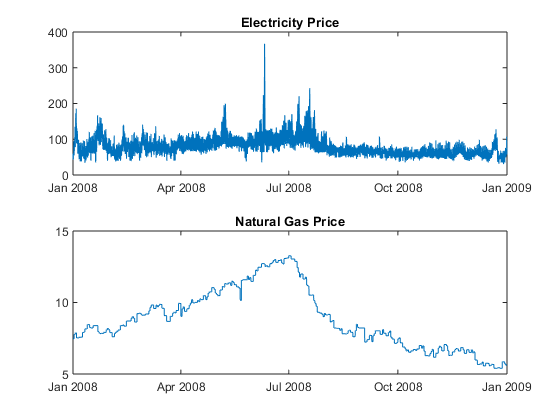

energy.Time = datetime(energy.Time,'ConvertFrom','datenum');
is2008 = (datetime(2008,1,1)<=energy.Time) & ...
    (energy.Time<datetime(2009,1,1));
energy2008 = energy(is2008,:);

figure
subplot(2,1,1)
plot(energy2008.Time, energy2008.Electricity);
title('Electricity Price')
datetick('x','mmm yyyy','keepticks')

subplot(2,1,2)
plot(energy2008.Time, energy2008.NaturalGas);
title('Natural Gas Price')
datetick('x','mmm yyyy','keepticks')